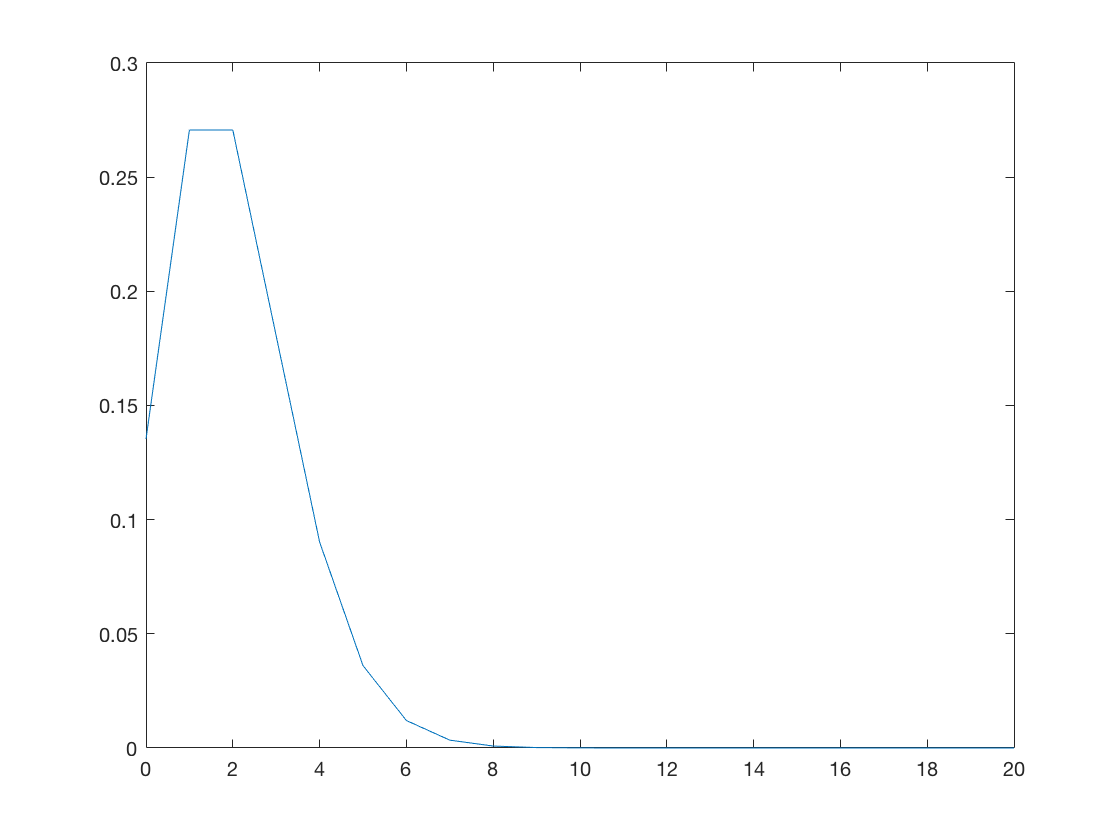

% PHYS 434
% LAB 2
% Jin Kyoung Lee


% Problem 1
% Background of cosmic-rays follow a Poisson distribution
% In 1 day the average cosmic-ray background: lambda(λ) = 2
% The average number of gamma-rays emitted by the hypothetical
% source: 4

% A) Cosmic-rays
% Day 1
x0 = linspace(0, 20, 21);
p0 = poisspdf(x0, 2); % Create Poisson distribution with lambda = 2
plot(x0, p0);

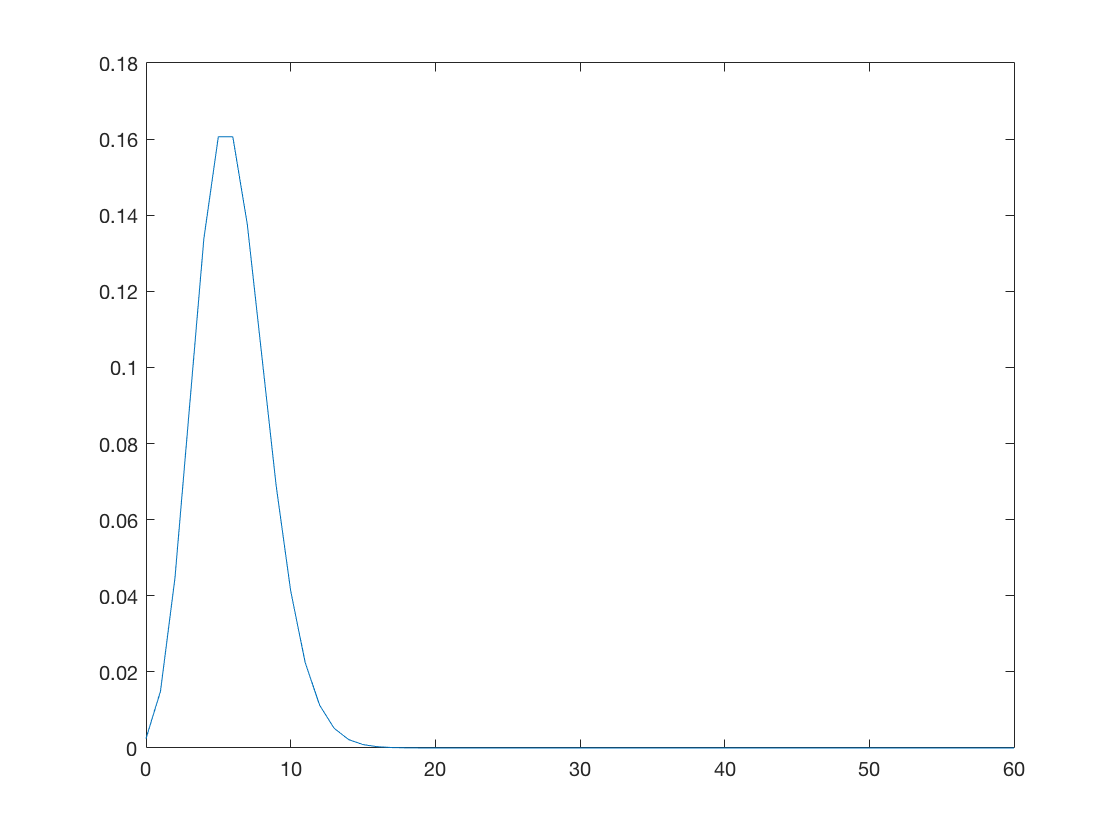

% Using convolution to get the probability distribution for more days
numOfDays = 3; % 3 days
p = p0;
for i = 1:numOfDays-1
    p = conv(p, p0);
end
x = linspace(0, 20*numOfDays, 20*numOfDays+1);
plot(x, p)

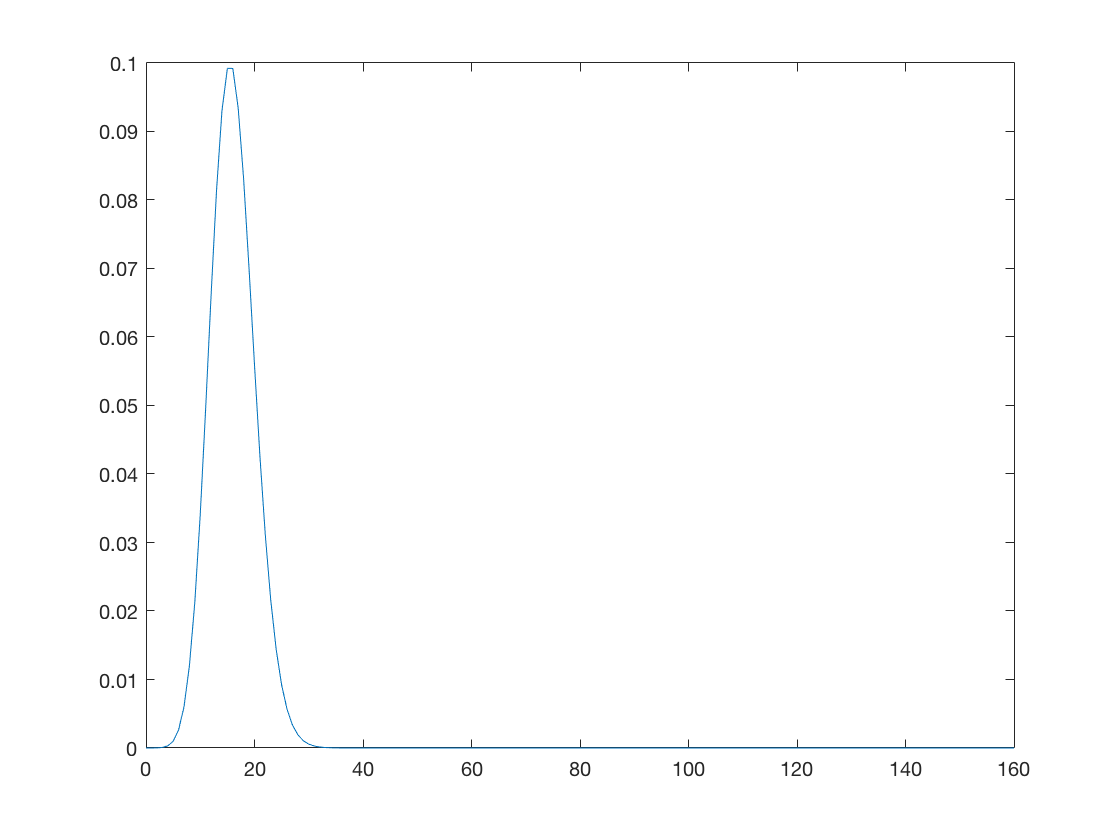

% From the result above, we can see that both the graph for a day and the
% graph for 3 days follow Poisson distribution.


% B)
% Also using convolution to get the probability distributino after 5 days
numOfDays = 8; % Choosing the value greater than 5
p = p0;
for i = 1:numOfDays-1
    p = conv(p, p0);
end
x = linspace(0, 20*numOfDays, 20*numOfDays+1);
plot(x, p)

% From part A), we found that adding probability distribution for 3 days
% was still a Poisson distribution. Also, here in part B), by using
% the same method that of part A), it is proved that after 5 days,the
% summed probability disdtribution is still A Poisson distribution.
% ******mathematical and conceptual explanation need to be added.******